# Demo:  Channel Estimation via Kernel Regression

In this demo, we demonstrate how to build a simple channel estimator using a common technique in estimation and machine learning called [kernel regression](https://en.wikipedia.org/wiki/Kernel_regression).  In going through this demo, you will learn to:

- Create raw channel estimates from reference signals

- Create smoothed channel estimates from kernel regression

- Estimate the noise via residual energy

- Measure the performance of the channel estimation via MSE and SNDR

- Measure the performance of the noise estimate

## Channel Parameters

We will illustrate the channel estimation over frequency for a single OFDM symbol.  In OFDM systems, you also have to estimate the channel over time.  Similar techniques can be applied and you will do this in the lab.  We use the following parameters which roughly correspond to a 10 MHz channel.

fc = 2.3e9;              % Carrier frequency
SubcarrierSpacing = 15;  % SCS in kHZ
NRB = 52;                % number of resource blocks
numScPerRB = 12;         % number of sub-carriers per RB
nsc = NRB*numScPerRB;    % total number of sub-carrier

We will a random instances of the channels for the test created by the function `randChan` below.  A typical realization of the channel is shown.

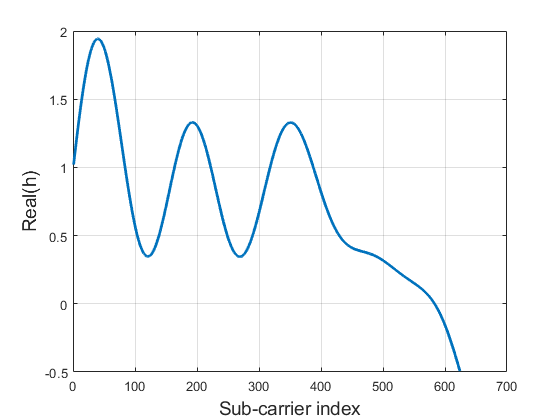

% Channel parameters
npaths = 20;       % number of paths
dlymean = 200e-9;  % mean delay spread in seconds

% Generate random channel
h = randChan(nsc,dlymean,SubcarrierSpacing);

% Plot the real component
clf
plot(real(h), 'LineWidth', 2);
grid on;
xlabel('Sub-carrier index', 'FontSize', 14);
ylabel('Real(h)', 'FontSize',14);

## Transmitting Reference Signals and Computing a Raw Channel Estimate

For the reference signals we will assume that the they are spaced once every 4 sub-carriers, which is one of the configurations in 5G NR.

% RS spacing
rsSpacing = 4;

% RS indices on the symbol
rsInd = (1:rsSpacing:nsc)';
nrs = length(rsInd);

% Random QPSK symbols
nbitsPerRS = 2;
M = 2^nbitsPerRS;
rsBits = randi([0,1], nrs*nbitsPerRS,1);
rsSym = qammod(rsBits, M, 'UnitAveragePower', true, ...
    'InputType', 'bit');

% TX vector with the reference signals
tx = zeros(nsc,1);
tx(rsInd) = rsSym;

% Modulate with channel and noise
snr = 10;
wvar = db2pow(-snr);
rx = h.*tx + sqrt(wvar/2)*(randn(nsc,1) + 1i*randn(nsc,1));

We compute the raw channel estimate by dviding the RX and TX symbols.  We see that these follow the trend of the the true channel, but are noisy.

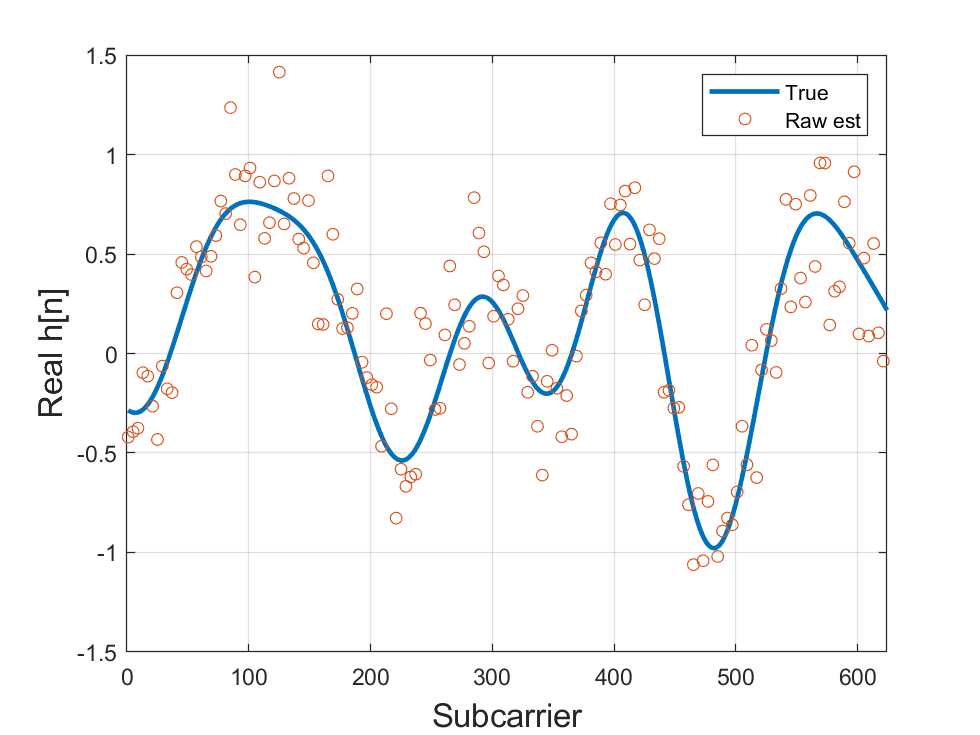


% Get the raw channel estimates on the RS
hestRS = rx(rsInd)./rsSym;

plot(real(h), 'LineWidth', 2);
hold on;
plot(rsInd, real(hestRS), 'o', 'Markersize', 5);
hold off;
grid on;
xlabel('Subcarrier', 'FontSize', 14);
ylabel('Real h[n]', 'Fontsize', 14);
xlim([0,nsc]);
legend('True', 'Raw est');

## Building a Kernel Regression Channel Estimate

To smooth out the noise in the raw channel estimate and to interpolate the channel estimate we use a simple kernel regresssion estimate.  We use a Gaussian kernel estimate, also called radial basis function (RBF).  We see the channel estimate is significantly smoothed out and provides a good estimate.

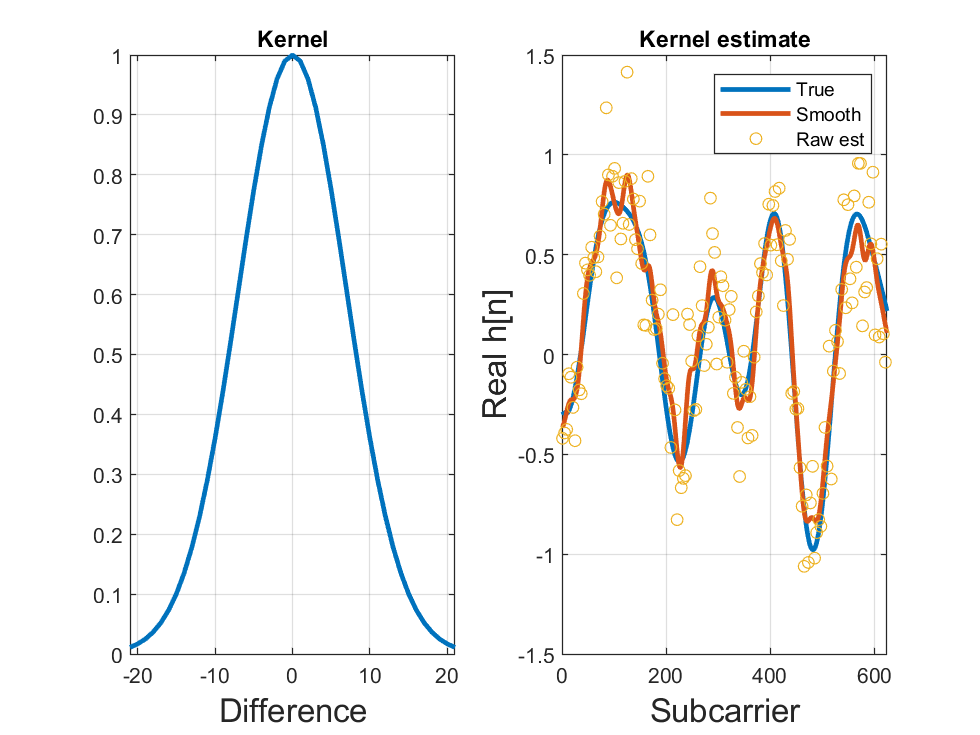

% Set the kernel parameters
sig = 7;
len = 3*sig;

% Compute the kernel regression estimate
[hest, w] = kernelReg(rsInd, hestRS, nsc, len, sig);

subplot(1,2,1);
plot((-len:len), w, 'LineWidth', 2);
grid on;
xlabel('Difference', 'FontSize', 14);
title('Kernel')

subplot(1,2,2);
plot(real([h hest]), 'LineWidth', 2);
hold on;
plot(rsInd, real(hestRS), 'o', 'Markersize', 5);
hold off;
grid on;
xlabel('Subcarrier', 'FontSize', 14);
ylabel('Real h[n]', 'Fontsize', 14);
xlim([0,nsc]);
legend('True', 'Smooth', 'Raw est');
title('Kernel estimate');

## Varying the Kernel Width

We now plot the result with a few different kernel widths to see the effect of the parameter.  We see that:

-  Too small width (`sig=2`)  results in overfitting with too much noise.

-  Too largel width (`sig=25`)  results in underfitting with too much bias error

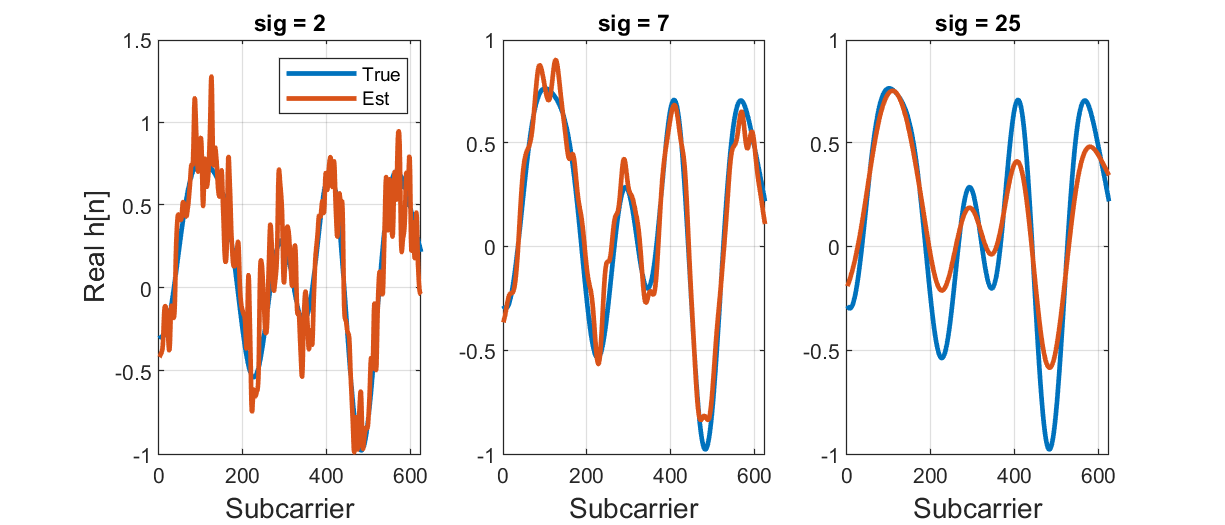

% Sigma values to test
sigTest = [2,7,25]';
ntest = length(sigTest);

% RS locations
rsSpacing = 4;
rsInd = (1:rsSpacing:nsc)';

clf;
for itest = 1:ntest
    
    % Construct the channel estimate
    sig = sigTest(itest);
    len = 3*sig;    
    hest = kernelReg(rsInd, hestRS, nsc, len, sig);
    
    % Plot the results
    subplot(1,ntest,itest);
    plot(real([h hest]), 'LineWidth', 2);
    grid on;    
    xlabel('Subcarrier', 'FontSize', 12);
    if (itest == 1)
        ylabel('Real h[n]', 'Fontsize', 12);
        legend('True', 'Est');
    end
    xlim([0,nsc]);    
    title(sprintf('sig = %d', sig));
end
set(gcf,'Position',[100 100 700 300]);

We can measure the MSE on the channel estimate over different `sigma` values.  We see that the optimal tradeoff of bias and variance error occurs at about `sig=7`.

% Values of kernel width to test
sigTest = linspace(1,25,10)';
ntest = length(sigTest);

% Parameters
ntrial = 100;       % Number of trials per kernel width
rsSpacing = 4;      % RS spacing
rsInd = (1:rsSpacing:nsc)';
dlymean = 200e-9;   % Channel delay spread
snr = 10;           % SNR [dB]

% Random QPSK symbols on the RS
rsBits = randi([0,1], nrs*nbitsPerRS,1);
rsSym = qammod(rsBits, M, 'UnitAveragePower', true, ...
    'InputType', 'bit');

% TX vector
tx = zeros(nsc,1);
tx(rsInd) = rsSym;

% Initialize vectors to store results
mse = zeros(ntrial, ntest);
mseAvg = zeros(ntest,1);

for itest = 1:ntest
    % Get the RBF parameters
    sig = sigTest(itest);
    len = ceil(3*sig);   
    
    % Test on large number of channels
    for i = 1:ntrial
        
        % Create random channel
        h = randChan(nsc, dlymean, SubcarrierSpacing);
        
        % Add noise
        wvar = db2pow(-snr);
        rx = h.*tx + sqrt(wvar/2)*(randn(nsc,1) + 1i*randn(nsc,1));
        
        % Get the raw channel estimates on the RS
        hestRaw = rx(rsInd)./rsSym;
        
        % Get channel estimate
        hest = kernelReg(rsInd, hestRaw, nsc, len, sig);
        
        % Measure the MSE
        mse(i, itest) = mean(abs(hest-h).^2);
    end
    
    mseAvg(itest) = 10*log10(mean(mse(:,itest)));
    fprintf('sig=%7.2f MSE=%7.2f\n', sig, mseAvg(itest));
end

sig=   1.00 MSE= -10.60
sig=   3.67 MSE= -15.07
sig=   6.33 MSE= -17.09
sig=   9.00 MSE= -17.68
sig=  11.67 MSE= -17.20
sig=  14.33 MSE= -16.14
sig=  17.00 MSE= -14.79
sig=  19.67 MSE= -13.74
sig=  22.33 MSE= -12.98
sig=  25.00 MSE= -11.58


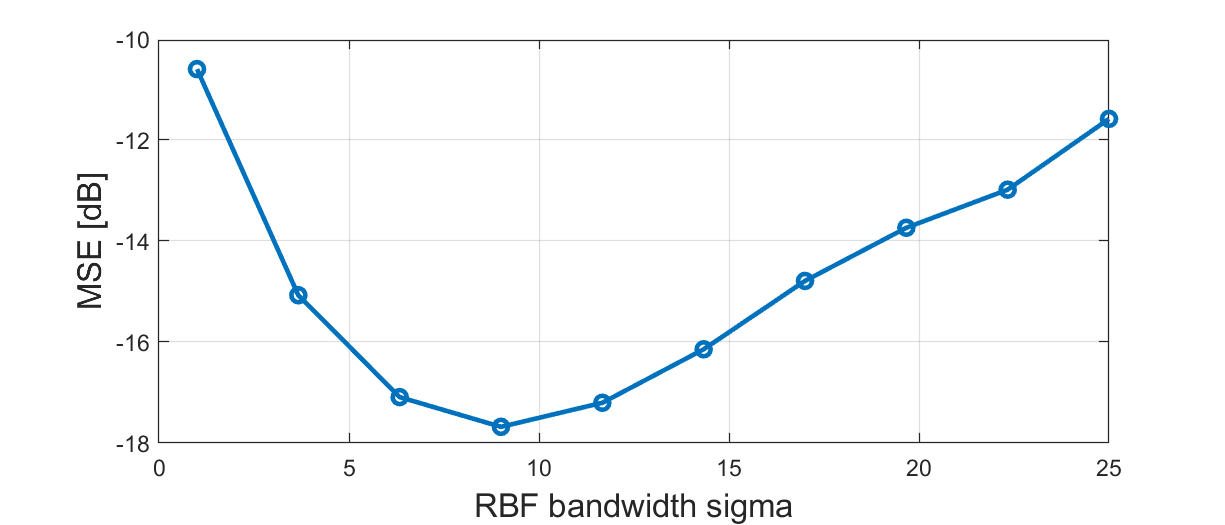

% PLot the MSE
clf;
plot(sigTest, mseAvg, 'o-','LineWidth', 2);
grid on;
xlabel('RBF bandwidth sigma', 'FontSize', 14);
ylabel('MSE [dB]', 'FontSize', 14);

## Signal-to-Noise+Distortion Ratio (SNDR)

The signal-to-noise+distortion ratio (SNDR) is a simple metric for quantifying the effect of the channel estimate.  It is the ratio of signal energy to the noise + distortion.  So, it models the channel estimation error as an additive increase in the noise.  It is usually plotted as a function of the SNR, so we see the effect of the channel estimation error.  

% Values of kernel width to test
snrTest = linspace(-5,45,20)';
ntest = length(snrTest);

% Parameters
sig = 7;      % Kernel width
len = 3*sig;  % kenel length
ntrial = 100;       % Number of trials per SNR
rsSpacing = 2;      % RS spacing
rsInd = (1:rsSpacing:nsc)';
dlymean = 200e-9;   % Channel delay spread

% Get the data indices
Idat = ones(nsc,1);
Idat(rsInd) = 0;
datInd = find(Idat);


% Initialize vectors to store results
noiseEff = zeros(ntrial, ntest);
noiseEst = zeros(ntrial, ntest);
sigEnergy = zeros(ntrial, ntest);
sndr = zeros(ntest,1);

for itest = 1:ntest
    % Get the SNR
    snr = snrTest(itest);    
    
    % Test on large number of channels
    for i = 1:ntrial
        
        % TX vector, populating all symbols with QPSK symbols
        nbits = 2*nsc;
        bits = randi([0,1], nbits, 1);
        M = 4;
        tx = qammod(bits, M, 'UnitAveragePower', true, 'InputType', 'bit');        
        
        % Create random channel
        h = randChan(nsc, dlymean, SubcarrierSpacing);        
        
        % Add noise
        wvar = db2pow(-snr);
        rx = h.*tx + sqrt(wvar/2)*(randn(nsc,1) + 1i*randn(nsc,1));
        
        % Get the raw channel estimates on the RS
        hestRaw = rx(rsInd)./tx(rsInd);
        
        % Get channel estimate
        hest = kernelReg(rsInd, hestRaw, nsc, len, sig);        
        
        % Measure signal power using the true channel and transmitted
        % symbols on the data symbols
        sigEnergy(i, itest) = mean(abs(h(datInd).*tx(datInd)).^2);
        
        % Measure the true effective noise = noise + distortion
        noiseEff(i,itest) = mean(abs(rx(datInd)-hest(datInd).*tx(datInd)).^2);               
        
        % Estimate the effective noise on the RS symbols.  
        noiseEst(i,itest) = mean(abs(rx(rsInd)-hest(rsInd).*tx(rsInd)).^2);   
                
    end 
        
    % Compute the SNDR
    sndr(itest) = pow2db(mean(sigEnergy(:,itest))/mean(noiseEff(:,itest)));
    
    fprintf('snr=%7.2f sndr=%7.2f\n', snr, sndr(itest));
end

snr=  -5.00 sndr=  -5.31
snr=  -2.37 sndr=  -2.78
snr=   0.26 sndr=  -0.36
snr=   2.89 sndr=   2.15
snr=   5.53 sndr=   4.82
snr=   8.16 sndr=   7.85
snr=  10.79 sndr=  10.14
snr=  13.42 sndr=  13.11
snr=  16.05 sndr=  15.31
snr=  18.68 sndr=  17.62
snr=  21.32 sndr=  20.44
snr=  23.95 sndr=  22.22
snr=  26.58 sndr=  24.01
snr=  29.21 sndr=  25.53
snr=  31.84 sndr=  26.07
snr=  34.47 sndr=  27.53
snr=  37.11 sndr=  27.90
snr=  39.74 sndr=  26.33
snr=  42.37 sndr=  27.48
snr=  45.00 sndr=  27.74


When we plot the results we see that at low SNRs, the channel estimation error degrades the SNR by a small amount (about 0.4 dB in this case).  As explained in the class notes, this loss is due to the variance.  But, at higher SNR, there is a saturation of the maximum SNR we can obtain.  As explained in the notes, this effect is the bias error.  

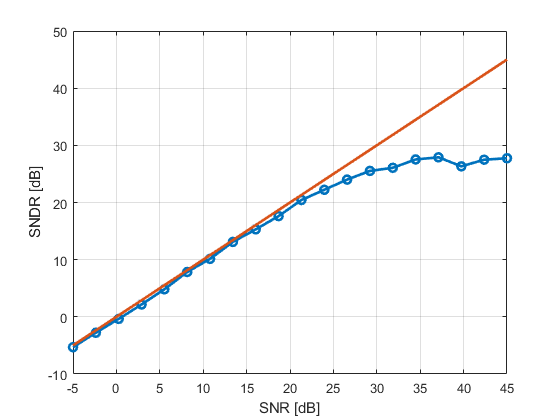

plot(snrTest, sndr, 'o-', 'LineWidth', 2);
hold on;
plot(snrTest, snrTest, '-', 'LineWidth', 2);
hold off;
grid on;
xlabel('SNR [dB]');
ylabel('SNDR [dB]');

## Noise Estimation Error

The previous simulation also plotted the noise estimate.  We can plot the error statistics

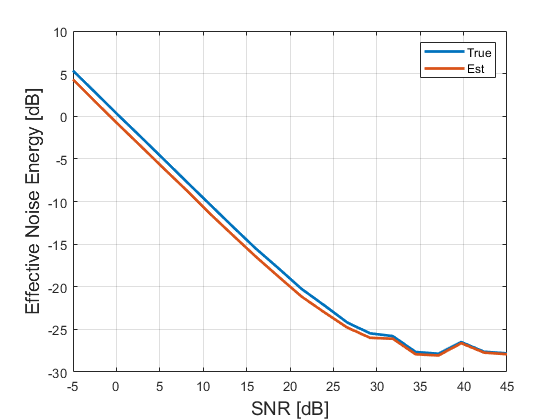

noiseEstAvg = pow2db(mean(noiseEst, 1))';
noiseTrueAvg = pow2db(mean(noiseEff, 1))';

plot(snrTest, noiseTrueAvg, '-', 'LineWidth', 2);
hold on;
plot(snrTest, noiseEstAvg, '-', 'LineWidth', 2);
grid on;
hold off;
xlabel('SNR [dB]', 'Fontsize', 14);
ylabel('Effective Noise Energy [dB]', 'Fontsize', 14);
legend('True', 'Est');

## In-Class Exercise:  Degradation in BER due to Channel Estimation

Modify the above program to:

- Populate the reference symbols with QPSK as before

- Populate the data symbols with 16-QAM

- Measure the BER on the data symbols as a function of the SNR for both perfect channel estimation and actual channel estimation.

- Plot the two BER values

% TODO


function h = randChan(nsc, dlymean, SubcarrierSpacing)
% Channel tap parameters
npaths = 20;       % number of paths
dly = exprnd(dlymean,npaths,1);

f = SubcarrierSpacing*1e3*(0:nsc-1)';
phaseInit = unifrnd(0,2*pi,1,npaths);
phase = 2*pi*f*dly' + phaseInit;
h = sum(exp(1i*phase),2)/sqrt(npaths);
end
